clc;
clear;
close all;

P01 = 20 * 1e5;     
T01 = 300;        
T03 = 300;        
T06 = 1100;         
P08 = P01 / 0.99;
P07 = P08 / 0.975; 

eta_c = 0.89;      
eta_t = 0.88;       
epsilon = 0.7;     
cp_air = 1.005;
gamma_air = 1.4;
MW_air = 28.97;
R_air = 8314 / MW_air;
cp_he = 5.193;      
gamma_he = 1.666;
MW_he = 4.003;      
R_he = 8314 / MW_he;  
rc_range = linspace(1.2, 30, 1000); 
N = length(rc_range);
eta_th_air = zeros(1, N);
W_net_air  = zeros(1, N);
eta_th_he  = zeros(1, N);
W_net_he   = zeros(1, N);
rho1_air = P01 / (R_air * T01);
rho1_he = P01 / (R_he * T01);

for i = 1:N
    rc = rc_range(i);
    
    P02_air = P01 * sqrt(rc);
    T02_air = T01 * (P02_air/P01)^((gamma_air-1)/(gamma_air*eta_c));
    P03_air = P02_air * 0.99;
    T03_air = T03; 
    P04_air = P01 * rc;
    T04_air = T03_air * (P04_air/P03_air)^((gamma_air-1)/(gamma_air*eta_c));
    P05_air = P04_air * 0.975;
    P06_air = P05_air * 0.97;
    T07_air = T06 * (P07/P06_air)^(((gamma_air-1)*eta_t)/gamma_air);
    T05_air = T04_air + epsilon * (T07_air - T04_air);

    wc1_air = cp_air * (T02_air - T01);
    wc2_air = cp_air * (T04_air - T03_air);
    wt_air = cp_air * (T06 - T07_air);
    wnet_mass_air = wt_air - (wc1_air + wc2_air);
    W_net_air(i) = wnet_mass_air * rho1_air; 
    qin_air = cp_air * (T06 - T05_air);
    eta_th_air(i) = (wnet_mass_air / qin_air) * 100; 

    P02_he = P01 * sqrt(rc);
    T02_he = T01 * (P02_he/P01)^((gamma_he-1)/(gamma_he*eta_c));
    P03_he = P02_he * 0.99;
    T03_he = T03;
    P04_he = P01 * rc;
    T04_he = T03_he * (P04_he/P03_he)^((gamma_he-1)/(gamma_he*eta_c));
    P05_he = P04_he * 0.975;
    P06_he = P05_he * 0.97;
    T07_he = T06 * (P07/P06_he)^(((gamma_he-1)*eta_t)/gamma_he);
    T05_he = T04_he + epsilon * (T07_he - T04_he);

    wc1_he = cp_he * (T02_he - T01);
    wc2_he = cp_he * (T04_he - T03_he);
    wt_he = cp_he * (T06 - T07_he);
    wnet_mass_he = wt_he - (wc1_he + wc2_he);
    W_net_he(i) = wnet_mass_he * rho1_he; 
    qin_he = cp_he * (T06 - T05_he);
    eta_th_he(i) = (wnet_mass_he / qin_he) * 100; 
    
end

## Plotting Results (task 2 & 3)

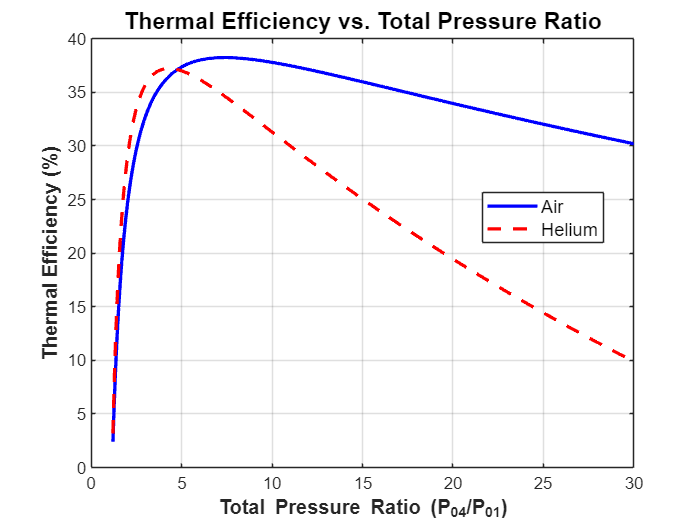


figure;
plot(rc_range, eta_th_air, 'b-', 'LineWidth', 2); hold on;
plot(rc_range, eta_th_he, 'r--', 'LineWidth', 2);
grid on;
xlabel('Total Pressure Ratio (P_{04}/P_{01})', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Thermal Efficiency (%)', 'FontSize', 12, 'FontWeight', 'bold');
title('Thermal Efficiency vs. Total Pressure Ratio', 'FontSize', 14);
legend('Air', 'Helium', 'Location', 'best', 'FontSize', 11);

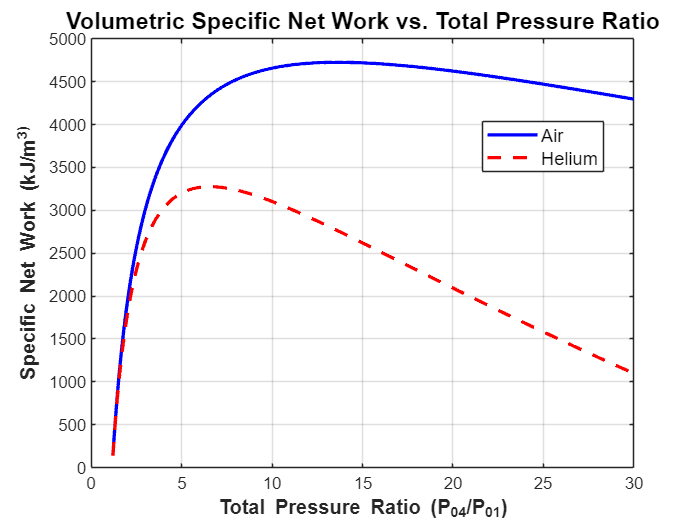

figure;
plot(rc_range, W_net_air, 'b-', 'LineWidth', 2); hold on;
plot(rc_range, W_net_he, 'r--', 'LineWidth', 2);
grid on;
xlabel('Total Pressure Ratio (P_{04}/P_{01})', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Specific Net Work (kJ/m^3)', 'FontSize', 12, 'FontWeight', 'bold');
title('Volumetric Specific Net Work vs. Total Pressure Ratio', 'FontSize', 14);
legend('Air', 'Helium', 'Location', 'best', 'FontSize', 11);

## Optimal point(task 4)

## Based on max efficiency


[~, idx_opt_air] = max(eta_th_air);
rc_opt_air = rc_range(idx_opt_air);
[~, idx_opt_he] = max(eta_th_he);
rc_opt_he = rc_range(idx_opt_he);

P02_a = P01 * sqrt(rc_opt_air);
T02_a = T01 * (P02_a/P01)^((gamma_air-1)/(gamma_air*eta_c));
P03_a = P02_a * 0.99;
T03_a = T03;
P04_a = P01 * rc_opt_air;
T04_a = T03_a * (P04_a/P03_a)^((gamma_air-1)/(gamma_air*eta_c));
P05_a = P04_a * 0.975;
P06_a = P05_a * 0.97;
T07_a = T06 * (P07/P06_a)^(((gamma_air-1)*eta_t)/gamma_air);
T05_a = T04_a + epsilon * (T07_a - T04_a);
T08_a = T07_a - (T05_a - T04_a);
P02_h = P01 * sqrt(rc_opt_he);
T02_h = T01 * (P02_h/P01)^((gamma_he-1)/(gamma_he*eta_c));
P03_h = P02_h * 0.99;
T03_h = T03;
P04_h = P01 * rc_opt_he;
T04_h = T03_h * (P04_h/P03_h)^((gamma_he-1)/(gamma_he*eta_c));
P05_h = P04_h * 0.975;
P06_h = P05_h * 0.97;
T07_h = T06 * (P07/P06_h)^(((gamma_he-1)*eta_t)/gamma_he);
T05_h = T04_h + epsilon * (T07_h - T04_h);
T08_h = T07_h - (T05_h - T04_h);

fprintf('Optimal point based on max efficiency');

Optimal point based on max efficiency

fprintf('Air (Pressure Ratio: %.2f - Efficiency: %.2f%% - Net Work: %.2f kJ/m^3)',rc_opt_air, eta_th_air(idx_opt_air), W_net_air(idx_opt_air));

Air (Pressure Ratio: 7.40 - Efficiency: 38.24% - Net Work: 4456.35 kJ/m^3)

fprintf('Point\t Pressure (bar)\t Temperature (K)\n');

Point	 Pressure (bar)	 Temperature (K)


fprintf('1\t\t %5.2f\t\t %6.2f\n', P01/1e5, T01);

1		 20.00		 300.00


fprintf('2\t\t %5.2f\t\t %6.2f\n', P02_a/1e5, T02_a);

2		 54.40		 413.65


fprintf('3\t\t %5.2f\t\t %6.2f\n', P03_a/1e5, T03_a);

3		 53.86		 300.00


fprintf('4\t\t %5.2f\t\t %6.2f\n', P04_a/1e5, T04_a);

4		 147.96		 414.98


fprintf('5\t\t %5.2f\t\t %6.2f\n', P05_a/1e5, T05_a);

5		 144.26		 600.84


fprintf('6\t\t %5.2f\t\t %6.2f\n', P06_a/1e5, T06);

6		 139.94		 1100.00


fprintf('7\t\t %5.2f\t\t %6.2f\n', P07/1e5, T07_a);

7		 20.72		 680.49


fprintf('8\t\t %5.2f\t\t %6.2f\n', P08/1e5, T08_a);

8		 20.20		 494.63



fprintf('HELIUM (Pressure Ratio: %.2f | Efficiency: %.2f%% | Net Work: %.2f kJ/m^3)',rc_opt_he, eta_th_he(idx_opt_he), W_net_he(idx_opt_he));

HELIUM (Pressure Ratio: 4.28 | Efficiency: 37.23% | Net Work: 3090.81 kJ/m^3)

fprintf('Point\t Pressure (bar)\t Temperature (K)\n');

Point	 Pressure (bar)	 Temperature (K)


fprintf('1\t\t %5.2f\t\t %6.2f\n', P01/1e5, T01);

1		 20.00		 300.00


fprintf('2\t\t %5.2f\t\t %6.2f\n', P02_h/1e5, T02_h);

2		 41.40		 415.95


fprintf('3\t\t %5.2f\t\t %6.2f\n', P03_h/1e5, T03_h);

3		 40.98		 300.00


fprintf('4\t\t %5.2f\t\t %6.2f\n', P04_h/1e5, T04_h);

4		 85.69		 417.83


fprintf('5\t\t %5.2f\t\t %6.2f\n', P05_h/1e5, T05_h);

5		 83.55		 601.91


fprintf('6\t\t %5.2f\t\t %6.2f\n', P06_h/1e5, T06);

6		 81.04		 1100.00


fprintf('7\t\t %5.2f\t\t %6.2f\n', P07/1e5, T07_h);

7		 20.72		 680.79


fprintf('8\t\t %5.2f\t\t %6.2f\n', P08/1e5, T08_h);

8		 20.20		 496.72


## Based on Max Net Work


[~, idx_opt_W_air] = max(W_net_air);
rc_opt_W_air = rc_range(idx_opt_W_air);
[~, idx_opt_W_he] = max(W_net_he);
rc_opt_W_he = rc_range(idx_opt_W_he);

P02_a_W = P01 * sqrt(rc_opt_W_air);
T02_a_W = T01 * (P02_a_W/P01)^((gamma_air-1)/(gamma_air*eta_c));
P03_a_W = P02_a_W * 0.99;
P04_a_W = P01 * rc_opt_W_air;
T04_a_W = T03_a * (P04_a_W/P03_a_W)^((gamma_air-1)/(gamma_air*eta_c));
P05_a_W = P04_a_W * 0.975;
P06_a_W = P05_a_W * 0.97;
T07_a_W = T06 * (P07/P06_a_W)^(((gamma_air-1)*eta_t)/gamma_air);
T05_a_W = T04_a_W + epsilon * (T07_a_W - T04_a_W);
T08_a_W = T07_a_W - (T05_a_W - T04_a_W);

P02_h_W = P01 * sqrt(rc_opt_W_he);
T02_h_W = T01 * (P02_h_W/P01)^((gamma_he-1)/(gamma_he*eta_c));
P03_h_W = P02_h_W * 0.99;
P04_h_W = P01 * rc_opt_W_he;
T04_h_W = T03_h * (P04_h_W/P03_h_W)^((gamma_he-1)/(gamma_he*eta_c));
P05_h_W = P04_h_W * 0.975;
P06_h_W = P05_h_W * 0.97;
T07_h_W = T06 * (P07/P06_h_W)^(((gamma_he-1)*eta_t)/gamma_he);
T05_h_W = T04_h_W + epsilon * (T07_h_W - T04_h_W);
T08_h_W = T07_h_W - (T05_h_W - T04_h_W);

fprintf('Optimal point based on Max Net Work');

Optimal point based on Max Net Work

fprintf('AIR (Pressure Ratio for Max Work: %.2f | Efficiency: %.2f%% | Net Work: %.2f kJ/m^3)',rc_opt_W_air, eta_th_air(idx_opt_W_air), W_net_air(idx_opt_W_air));

AIR (Pressure Ratio for Max Work: 13.63 | Efficiency: 36.53% | Net Work: 4725.29 kJ/m^3)

fprintf('Point\t Pressure (bar)\t Temperature (K)\n');

Point	 Pressure (bar)	 Temperature (K)


fprintf('1\t\t %5.2f\t\t %6.2f\n', P01/1e5, T01);

1		 20.00		 300.00


fprintf('2\t\t %5.2f\t\t %6.2f\n', P02_a_W/1e5, T02_a_W);

2		 73.82		 456.25


fprintf('3\t\t %5.2f\t\t %6.2f\n', P03_a_W/1e5, T03_a);

3		 73.09		 300.00


fprintf('4\t\t %5.2f\t\t %6.2f\n', P04_a_W/1e5, T04_a_W);

4		 272.50		 457.72


fprintf('5\t\t %5.2f\t\t %6.2f\n', P05_a_W/1e5, T05_a_W);

5		 265.69		 545.86


fprintf('6\t\t %5.2f\t\t %6.2f\n', P06_a_W/1e5, T06);

6		 257.72		 1100.00


fprintf('7\t\t %5.2f\t\t %6.2f\n', P07/1e5, T07_a_W);

7		 20.72		 583.63


fprintf('8\t\t %5.2f\t\t %6.2f\n', P08/1e5, T08_a_W);

8		 20.20		 495.49



fprintf('HELIUM (Pressure Ratio for Max Work: %.2f | Efficiency: %.2f%% | Net Work: %.2f kJ/m^3)',rc_opt_W_he, eta_th_he(idx_opt_W_he), W_net_he(idx_opt_W_he));

HELIUM (Pressure Ratio for Max Work: 6.56 | Efficiency: 35.60% | Net Work: 3274.79 kJ/m^3)

fprintf('Point\t Pressure (bar)\t Temperature (K)\n');

Point	 Pressure (bar)	 Temperature (K)


fprintf('1\t\t %5.2f\t\t %6.2f\n', P01/1e5, T01);

1		 20.00		 300.00


fprintf('2\t\t %5.2f\t\t %6.2f\n', P02_h_W/1e5, T02_h_W);

2		 51.23		 457.74


fprintf('3\t\t %5.2f\t\t %6.2f\n', P03_h_W/1e5, T03_h);

3		 50.72		 300.00


fprintf('4\t\t %5.2f\t\t %6.2f\n', P04_h_W/1e5, T04_h_W);

4		 131.24		 459.81


fprintf('5\t\t %5.2f\t\t %6.2f\n', P05_h_W/1e5, T05_h_W);

5		 127.96		 548.14


fprintf('6\t\t %5.2f\t\t %6.2f\n', P06_h_W/1e5, T06);

6		 124.12		 1100.00


fprintf('7\t\t %5.2f\t\t %6.2f\n', P07/1e5, T07_h_W);

7		 20.72		 585.99


fprintf('8\t\t %5.2f\t\t %6.2f\n', P08/1e5, T08_h_W);

8		 20.20		 497.66


## Utopia Point Optimization

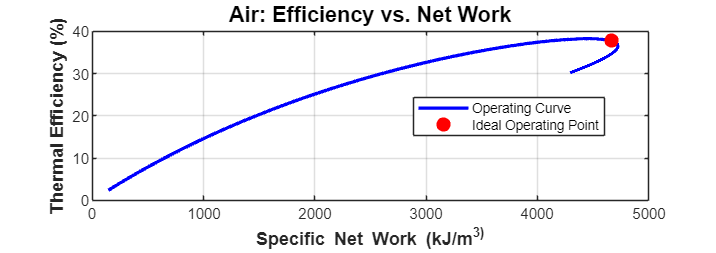


W_norm_air = (W_net_air - min(W_net_air)) / (max(W_net_air) - min(W_net_air));
eta_norm_air = (eta_th_air - min(eta_th_air)) / (max(eta_th_air) - min(eta_th_air));
dist_air = sqrt((W_norm_air - 1).^2 + (eta_norm_air - 1).^2);
[~, idx_utopia_air] = min(dist_air);
rc_utopia_air = rc_range(idx_utopia_air);
W_norm_he = (W_net_he - min(W_net_he)) / (max(W_net_he) - min(W_net_he));
eta_norm_he = (eta_th_he - min(eta_th_he)) / (max(eta_th_he) - min(eta_th_he));
dist_he = sqrt((W_norm_he - 1).^2 + (eta_norm_he - 1).^2);
[~, idx_utopia_he] = min(dist_he);
rc_utopia_he = rc_range(idx_utopia_he);

figure('Units', 'normalized', 'Position', [0.1, 0.2, 0.8, 0.5]);
plot(W_net_air, eta_th_air, 'b-', 'LineWidth', 2); hold on;
plot(W_net_air(idx_utopia_air), eta_th_air(idx_utopia_air), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
grid on; box on;
xlabel('Specific Net Work (kJ/m^3)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Thermal Efficiency (%)', 'FontSize', 11, 'FontWeight', 'bold');
title('Air: Efficiency vs. Net Work', 'FontSize', 13);
legend('Operating Curve', 'Ideal Operating Point', 'Location', 'best');

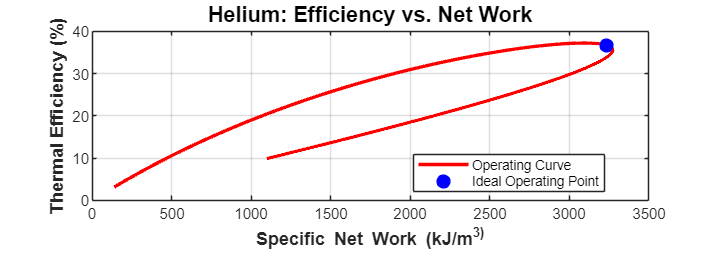


figure('Units', 'normalized', 'Position', [0.1, 0.2, 0.8, 0.5]);
plot(W_net_he, eta_th_he, 'r-', 'LineWidth', 2); hold on;
plot(W_net_he(idx_utopia_he), eta_th_he(idx_utopia_he), 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
grid on; box on;
xlabel('Specific Net Work (kJ/m^3)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Thermal Efficiency (%)', 'FontSize', 11, 'FontWeight', 'bold');
title('Helium: Efficiency vs. Net Work', 'FontSize', 13);
legend('Operating Curve', 'Ideal Operating Point', 'Location', 'best');


P02_a_U = P01 * sqrt(rc_utopia_air);
T02_a_U = T01 * (P02_a_U/P01)^((gamma_air-1)/(gamma_air*eta_c));
P03_a_U = P02_a_U * 0.99;
P04_a_U = P01 * rc_utopia_air;
T04_a_U = T03 * (P04_a_U/P03_a_U)^((gamma_air-1)/(gamma_air*eta_c));
P05_a_U = P04_a_U * 0.975;
P06_a_U = P05_a_U * 0.97;
T07_a_U = T06 * (P07/P06_a_U)^(((gamma_air-1)*eta_t)/gamma_air);
T05_a_U = T04_a_U + epsilon * (T07_a_U - T04_a_U);
T08_a_U = T07_a_U - (T05_a_U - T04_a_U);

P02_h_U = P01 * sqrt(rc_utopia_he);
T02_h_U = T01 * (P02_h_U/P01)^((gamma_he-1)/(gamma_he*eta_c));
P03_h_U = P02_h_U * 0.99;
P04_h_U = P01 * rc_utopia_he;
T04_h_U = T03 * (P04_h_U/P03_h_U)^((gamma_he-1)/(gamma_he*eta_c));
P05_h_U = P04_h_U * 0.975;
P06_h_U = P05_h_U * 0.97;
T07_h_U = T06 * (P07/P06_h_U)^(((gamma_he-1)*eta_t)/gamma_he);
T05_h_U = T04_h_U + epsilon * (T07_h_U - T04_h_U);
T08_h_U = T07_h_U - (T05_h_U - T04_h_U);

fprintf('Utopia Point Optimization ');

Utopia Point Optimization 

fprintf('AIR (Trade-off Pressure Ratio: %.2f | Efficiency: %.2f%% | Net Work: %.2f kJ/m^3)',rc_utopia_air, eta_th_air(idx_utopia_air), W_net_air(idx_utopia_air));

AIR (Trade-off Pressure Ratio: 10.19 | Efficiency: 37.74% | Net Work: 4665.13 kJ/m^3)

fprintf('Point\t Pressure (bar)\t Temperature (K)');

Point	 Pressure (bar)	 Temperature (K)

fprintf('1\t\t %5.2f\t\t %6.2f\n', P01/1e5, T01);

1		 20.00		 300.00


fprintf('2\t\t %5.2f\t\t %6.2f\n', P02_a_U/1e5, T02_a_U);

2		 63.86		 435.49


fprintf('3\t\t %5.2f\t\t %6.2f\n', P03_a_U/1e5, T03);

3		 63.22		 300.00


fprintf('4\t\t %5.2f\t\t %6.2f\n', P04_a_U/1e5, T04_a_U);

4		 203.89		 436.90


fprintf('5\t\t %5.2f\t\t %6.2f\n', P05_a_U/1e5, T05_a_U);

5		 198.79		 570.52


fprintf('6\t\t %5.2f\t\t %6.2f\n', P06_a_U/1e5, T06);

6		 192.83		 1100.00


fprintf('7\t\t %5.2f\t\t %6.2f\n', P07/1e5, T07_a_U);

7		 20.72		 627.79


fprintf('8\t\t %5.2f\t\t %6.2f\n', P08/1e5, T08_a_U);

8		 20.20		 494.16


fprintf(' HELIUM (Trade-off Pressure Ratio: %.2f | Efficiency: %.2f%% | Net Work: %.2f kJ/m^3)',rc_utopia_he, eta_th_he(idx_utopia_he), W_net_he(idx_utopia_he));

 HELIUM (Trade-off Pressure Ratio: 5.38 | Efficiency: 36.74% | Net Work: 3235.14 kJ/m^3)

fprintf('Point\t Pressure (bar)\t Temperature (K)\n');

Point	 Pressure (bar)	 Temperature (K)


fprintf('1\t\t %5.2f\t\t %6.2f\n', P01/1e5, T01);

1		 20.00		 300.00


fprintf('2\t\t %5.2f\t\t %6.2f\n', P02_h_U/1e5, T02_h_U);

2		 46.39		 437.77


fprintf('3\t\t %5.2f\t\t %6.2f\n', P03_h_U/1e5, T03);

3		 45.93		 300.00


fprintf('4\t\t %5.2f\t\t %6.2f\n', P04_h_U/1e5, T04_h_U);

4		 107.60		 439.75


fprintf('5\t\t %5.2f\t\t %6.2f\n', P05_h_U/1e5, T05_h_U);

5		 104.91		 571.80


fprintf('6\t\t %5.2f\t\t %6.2f\n', P06_h_U/1e5, T06);

6		 101.77		 1100.00


fprintf('7\t\t %5.2f\t\t %6.2f\n', P07/1e5, T07_h_U);

7		 20.72		 628.39


fprintf('8\t\t %5.2f\t\t %6.2f\n', P08/1e5, T08_h_U);

8		 20.20		 496.34


## Heat Exchanger effect on efficiency (task 5)

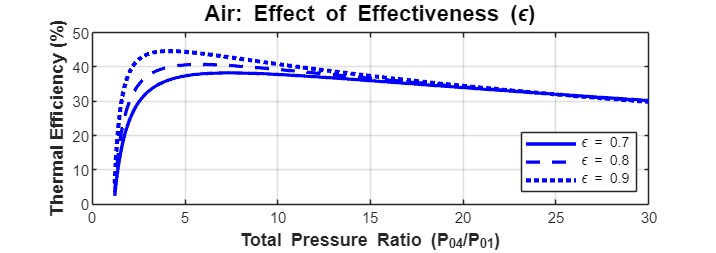


epsilon_array = [0.7, 0.8, 0.9];
num_eps = length(epsilon_array);
eta_th_air_eps = zeros(num_eps, N);
eta_th_he_eps  = zeros(num_eps, N);

for k = 1:num_eps
    eps_current = epsilon_array(k);
    
    for i = 1:N
        rc = rc_range(i);

        P02_a = P01 * sqrt(rc);
        P03_a = P02_a * 0.99;
        P04_a = P01 * rc;
        P05_a = P04_a * 0.975;
        P06_a = P05_a * 0.97;
        T02_a = T01 * (P02_a/P01)^((gamma_air-1)/(gamma_air*eta_c));
        T04_a = T03 * (P04_a/P03_a)^((gamma_air-1)/(gamma_air*eta_c));
        T07_a = T06 * (P07/P06_a)^(((gamma_air-1)*eta_t)/gamma_air);
        T05_a = T04_a + eps_current * (T07_a - T04_a);

        wc1_a = cp_air * (T02_a - T01);
        wc2_a = cp_air * (T04_a - T03);
        wt_a  = cp_air * (T06 - T07_a);
        wnet_a = wt_a - (wc1_a + wc2_a);
        qin_a  = cp_air * (T06 - T05_a);
        eta_th_air_eps(k, i) = (wnet_a / qin_a) * 100;

        P02_h = P01 * sqrt(rc);
        P03_h = P02_h * 0.99;
        P04_h = P01 * rc;
        P05_h = P04_h * 0.975;
        P06_h = P05_h * 0.97;
        T02_h = T01 * (P02_h/P01)^((gamma_he-1)/(gamma_he*eta_c));
        T04_h = T03 * (P04_h/P03_h)^((gamma_he-1)/(gamma_he*eta_c));
        T07_h = T06 * (P07/P06_h)^(((gamma_he-1)*eta_t)/gamma_he);
        T05_h = T04_h + eps_current * (T07_h - T04_h);
        
        wc1_h = cp_he * (T02_h - T01);
        wc2_h = cp_he * (T04_h - T03);
        wt_h  = cp_he * (T06 - T07_h);
        wnet_h = wt_h - (wc1_h + wc2_h);
        qin_h  = cp_he * (T06 - T05_h);
        eta_th_he_eps(k, i) = (wnet_h / qin_h) * 100;
    end
end

figure('Units', 'normalized', 'Position', [0.1, 0.2, 0.8, 0.5]);
plot(rc_range, eta_th_air_eps(1,:), 'b-',  'LineWidth', 2); hold on;
plot(rc_range, eta_th_air_eps(2,:), 'b--', 'LineWidth', 2);
plot(rc_range, eta_th_air_eps(3,:), 'b:',  'LineWidth', 2.5);
grid on; box on;
xlabel('Total Pressure Ratio (P_{04}/P_{01})', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Thermal Efficiency (%)', 'FontSize', 11, 'FontWeight', 'bold');
title('Air: Effect of Effectiveness (\epsilon)', 'FontSize', 13);
legend('\epsilon = 0.7', '\epsilon = 0.8', '\epsilon = 0.9', 'Location', 'best');

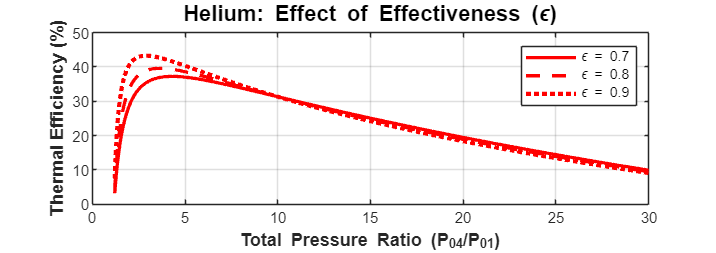


figure('Units', 'normalized', 'Position', [0.1, 0.2, 0.8, 0.5]);
plot(rc_range, eta_th_he_eps(1,:), 'r-',  'LineWidth', 2); hold on;
plot(rc_range, eta_th_he_eps(2,:), 'r--', 'LineWidth', 2);
plot(rc_range, eta_th_he_eps(3,:), 'r:',  'LineWidth', 2.5);
grid on; box on;
xlabel('Total Pressure Ratio (P_{04}/P_{01})', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Thermal Efficiency (%)', 'FontSize', 11, 'FontWeight', 'bold');
title('Helium: Effect of Effectiveness (\epsilon)', 'FontSize', 13);
legend('\epsilon = 0.7', '\epsilon = 0.8', '\epsilon = 0.9', 'Location', 'best');

## task 6 - Heat exchanger properties and cost comparison

%%Cohen section 2.6:
%%Nu = 0.023 Re^0.8 Pr^0.4
%%h_He / h_air ≈ 1.86 
eps_opt = 0.9;
NTU_opt = eps_opt / (1 - eps_opt);
fprintf('NTU = epsilon/(1-epsilon) = %.3f\n', NTU_opt);

NTU = epsilon/(1-epsilon) = 9.000



rc6_air = rc_utopia_air;
rc6_he  = rc_utopia_he;

P02_a = P01 * sqrt(rc6_air);
T02_a = T01 * (P02_a/P01)^((gamma_air-1)/(gamma_air*eta_c));
P03_a = P02_a * 0.99;
T03_a = T03;
P04_a = P01 * rc6_air;
T04_a = T03_a * (P04_a/P03_a)^((gamma_air-1)/(gamma_air*eta_c));
P05_a = P04_a * 0.975;
P06_a = P05_a * 0.97;
P08_a = P08;
P07_a = P07;
T07_a = T06 * (P07_a/P06_a)^(((gamma_air-1)*eta_t)/gamma_air);
T05_a = T04_a + eps_opt * (T07_a - T04_a);
T08_a = T07_a - (T05_a - T04_a);

Tmean_HX_air = mean([T04_a, T05_a, T07_a, T08_a]);

P02_h = P01 * sqrt(rc6_he);
T02_h = T01 * (P02_h/P01)^((gamma_he-1)/(gamma_he*eta_c));
P03_h = P02_h * 0.99;
T03_h = T03;
P04_h = P01 * rc6_he;
T04_h = T03_h * (P04_h/P03_h)^((gamma_he-1)/(gamma_he*eta_c));
P05_h = P04_h * 0.975;
P06_h = P05_h * 0.97;
P08_h = P08;
P07_h = P07;
T07_h = T06 * (P07_h/P06_h)^(((gamma_he-1)*eta_t)/gamma_he);
T05_h = T04_h + eps_opt * (T07_h - T04_h);
T08_h = T07_h - (T05_h - T04_h);

Tmean_HX_he = mean([T04_h, T05_h, T07_h, T08_h]);

fprintf('Air HX mean temperature = %.3f K\n', Tmean_HX_air);

Air HX mean temperature = 532.342 K


fprintf('Helium HX mean temperature = %.3f K\n', Tmean_HX_he);

Helium HX mean temperature = 534.072 K



%%assume
Cdot_basis = 1.0;
U_air = 0.100;

%% @ mean HX temperature
T_air_table = [300 350 400 450 500 550 600 650 700 750 800 850 900 950 1000 1100 1200 1300 1400 1500 1600];
mu_air_table = [184.6 208.2 230.1 250.7 270.1 288.4 305.8 322.5 338.8 354.6 369.8 384.3 398.1 411.3 424.4 449.0 473.0 496.0 530.0 557.0 584.0];
k_air_table = [26.3 30.0 33.8 37.3 40.7 43.9 46.9 49.7 52.4 54.9 57.3 59.6 62.0 64.3 66.7 71.5 76.3 82.0 91.0 100.0 106.0];

T_he_table = [300 350 400 450 500 600 650 700 750 800 900 1000];
mu_he_table = [199 221 243 263 283 320 332 350 364 382 414 446];
k_he_table = [152 170 187 204 220 252 264 278 291 304 330 354];

mu_air_HX = interp1(T_air_table, mu_air_table, Tmean_HX_air, 'linear', 'extrap');
k_air_HX  = interp1(T_air_table, k_air_table, Tmean_HX_air, 'linear', 'extrap');

mu_he_HX = interp1(T_he_table, mu_he_table, Tmean_HX_he, 'linear', 'extrap');
k_he_HX  = interp1(T_he_table, k_he_table, Tmean_HX_he, 'linear', 'extrap');

rho_ratio = R_air / R_he;
mu_ratio  = mu_he_HX / mu_air_HX;
k_ratio   = k_he_HX / k_air_HX;

C_ratio = (1 / (rho_ratio^0.75 * mu_ratio^0.25))^(1/1.75);
Re_ratio = rho_ratio * C_ratio / mu_ratio;

h_ratio_calc = (Re_ratio^0.8) * k_ratio;
h_ratio_cohen = 1.86;

if abs(h_ratio_calc - h_ratio_cohen)/h_ratio_cohen > 0.10
    h_ratio = h_ratio_cohen;
else
    h_ratio = h_ratio_calc;
end

U_he = h_ratio * U_air;

fprintf('rho_He/rho_air at HX = %.3f\n', rho_ratio);

rho_He/rho_air at HX = 0.138


fprintf('mu_He/mu_air at HX = %.3f\n', mu_ratio);

mu_He/mu_air at HX = 1.048


fprintf('k_He/k_air at HX = %.3f\n', k_ratio);

k_He/k_air at HX = 5.399


fprintf('Calculated h_He/h_air = %.3f\n', h_ratio_calc);

Calculated h_He/h_air = 2.092


fprintf('Used h_He/h_air = %.3f\n', h_ratio);

Used h_He/h_air = 1.860


fprintf('Calculated U_He/U_air = %.3f\n', U_he/U_air);

Calculated U_He/U_air = 1.860



A_air = NTU_opt * Cdot_basis / U_air;
A_he  = NTU_opt * Cdot_basis / U_he;

area_ratio = A_he / A_air;
area_reduction_percent = (1 - area_ratio) * 100;

fprintf('A_air = %.3f m^2\n', A_air);

A_air = 90.000 m^2


fprintf('A_He  = %.3f m^2\n', A_he);

A_He  = 48.387 m^2


fprintf('A_He/A_air = %.3f\n', area_ratio);

A_He/A_air = 0.538


fprintf('Helium heat exchanger area reduction = %.2f %%\n', area_reduction_percent);

Helium heat exchanger area reduction = 46.24 %



alpha = 15;

M_air = alpha * A_air;
M_he  = alpha * A_he;

mass_reduction_percent = (1 - M_he / M_air) * 100;

fprintf('M_air = %.3f kg\n', M_air);

M_air = 1350.000 kg


fprintf('M_He  = %.3f kg\n', M_he);

M_He  = 725.806 kg


fprintf('Mass reduction = %.2f %%\n', mass_reduction_percent);

Mass reduction = 46.24 %



C0 = @(A) 10.^(4.3247 - 0.3030 .* log10(A) + ...
               0.1634 .* (log10(A)).^2);

Cost_air = C0(A_air);
Cost_he  = C0(A_he);

cost_reduction_percent = (1 - Cost_he / Cost_air) * 100;

fprintf('Cost_air = %.2f USD\n', Cost_air);

Cost_air = 22730.01 USD


fprintf('Cost_He  = %.2f USD\n', Cost_he);

Cost_He  = 18967.38 USD


fprintf('Cost reduction = %.2f %%\n', cost_reduction_percent);

Cost reduction = 16.55 %
